heightmap=read(Tiff('\\lfs.lifesci.dundee.ac.uk\lfs\cjw\Jason\cable detection\exp0186\h_map\h_map_Exp186_0435.tif','r'));

Input some additional information here:

lengthunit_name = "pixel" %for example, "nm"

lengthunit_name = "pixel"

voxel_size_x = 1; 
voxel_size_y = 1;
voxel_size_z = 1; %in chosen length unit

tile_size= 180;

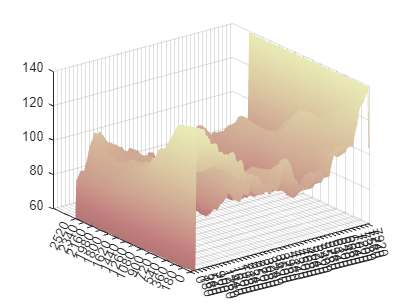

figure
mesh(heightmap);
zlim([60, 140]);
shading interp;
colormap(pink);
ax=gca;
ax.YTick = 0:tile_size:2560;
ax.XTick = 0:tile_size:7951;

Analysis for metric (first fundamental form) and metric determinant

Try smoothin heightmap first.  Cell scale = 10 to 30 pixels.

h_smooth = imgaussfilt(double(heightmap), 15);
figure
mesh(h_smooth);
zlim([60, 140]);
shading interp;
colormap(pink);
ax=gca;
ax.YTick = 0:tile_size:2560;
ax.XTick = 0:tile_size:7951;
axis equal

[diff_x, diff_y] = gradient(double(h_smooth)); %central difference
gxx =  1+diff_x.^2;
gyy =  1+diff_y.^2;
gxy= diff_x.*diff_y;
sqrtg = sqrt(gxx.*gyy - gxy.^2);

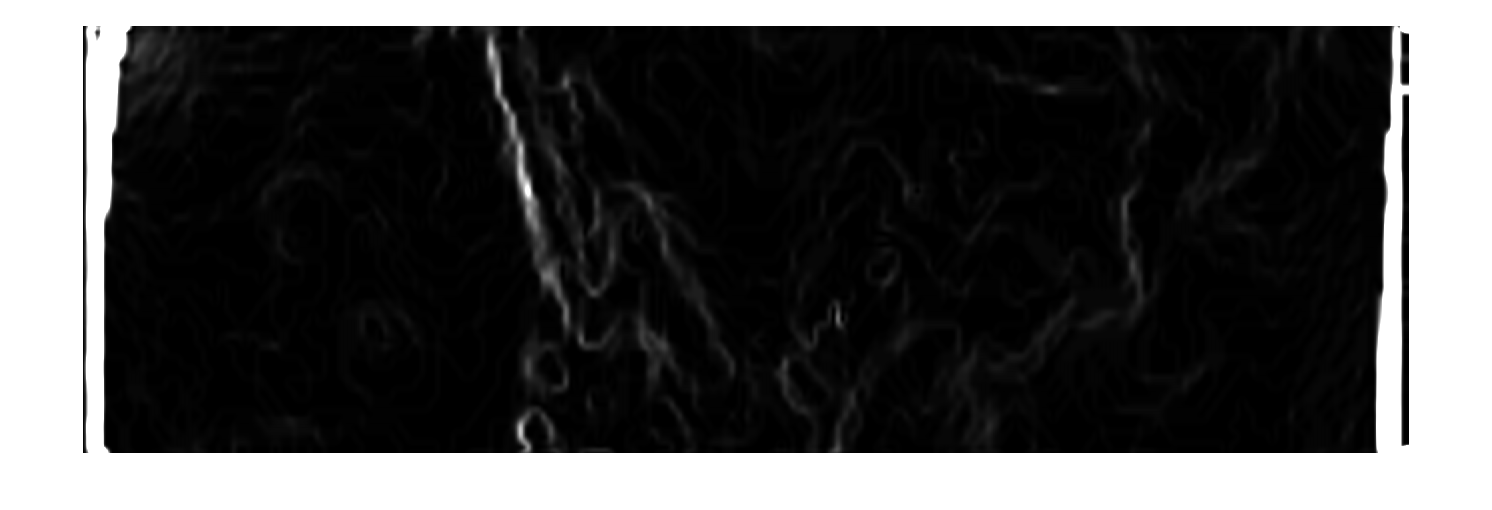

imshow(sqrtg,[1,1.05]);

%need second derivatives
%applying the second derivative opreator del2 rowwise/columnwise
del2x = splitapply(@(x) del2(x), h_smooth, 1:size(h_smooth,2));
del2y= splitapply(@(x) del2(x), h_smooth', 1:size(h_smooth,1));
del2y=del2y';
[crossdel,~] = gradient(diff_x);
%checked: del2x+del2y = del2(h_smooth)
factor = 1./sqrt(1+diff_x.^2+diff_y.^2)
Gaussian_curvature = (del2x.*del2y+crossdel).*factor.^2;
mean_curvature = ((1+diff_x.^2).*del2y+(1+diff_y.^2).*del2x- ...
    -2.*diff_x.*diff_y.*crossdel)*0.5.*factor.^2;

Fit planes for each tile

% a plane can be defined by a point and two linearly independed vectors
%point - center of fitted plane, average height of datapoint - but not
%necessary
% vectors - slope of linear fit in x, y directions
tile_start_x = 1200;
tile_start_y = 1200;
heights_tile = h_smooth(tile_start_x:tile_start_x+tile_size-1,tile_start_x:tile_start_x+tile_size-1);

%as 1D lists of coordinates
xs = reshape(repmat(tile_start_x:tile_start_x+tile_size-1, tile_size,1),[],1);
ys = reshape(repmat((tile_start_y:tile_start_y+tile_size-1)', 1, tile_size),[],1);
zs = reshape(heights_tile,[], 1);

planefit = fit([xs,ys], zs, 'poly11');
